clc;
clear;
close all;
% (====LOADING DATA IN TO MATLAB=====)
imagefolder= imageDatastore("C:\Users\AMI GENT\OneDrive\Desktop\leaf photos")

imagefolder =   ImageDatastore with properties:

                       Files: {
                              'C:\Users\AMI GENT\OneDrive\Desktop\leaf photos\leaf 1.jpeg';
                              'C:\Users\AMI GENT\OneDrive\Desktop\leaf photos\leaf 2.jpeg';
                              'C:\Users\AMI GENT\OneDrive\Desktop\leaf photos\leaf 3.jpeg'
                               ... and 4 more
                              }
                     Folders: {
                              'C:\Users\AMI GENT\OneDrive\Desktop\leaf photos'
                              }
    AlternateFileSystemRoots: {}
                    ReadSize: 1
                      Labels: {}
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatastoreImage


D=imagefolder

D =   ImageDatastore with properties:

                       Files: {
                              'C:\Users\AMI GENT\OneDrive\Desktop\leaf photos\leaf 1.jpeg';
                              'C:\Users\AMI GENT\OneDrive\Desktop\leaf photos\leaf 2.jpeg';
                              'C:\Users\AMI GENT\OneDrive\Desktop\leaf photos\leaf 3.jpeg'
                               ... and 4 more
                              }
                     Folders: {
                              'C:\Users\AMI GENT\OneDrive\Desktop\leaf photos'
                              }
    AlternateFileSystemRoots: {}
                    ReadSize: 1
                      Labels: {}
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatastoreImage


Leaves = struct with fields:
              Name: 'botleaf'
          LEAFTYPE: 'simple'
      LeafVenation: 'network'
             shape: 'oval'
           texture: 'rough'
          original: [1280×1280×3 uint8]
         Grayimage: [1280×1280 uint8]
       Binaryimage: [1280×1280 logical]
           EdgeImg: [1280×1280 logical]
    Processedimage: [1280×1280 logical]


Leaves = 1×2 struct array with fields:
    Name
    LEAFTYPE
    LeafVenation
    shape
    texture
    original
    Grayimage
    Binaryimage
    EdgeImg
    Processedimage


Leaves = 1×3 struct array with fields:
    Name
    LEAFTYPE
    LeafVenation
    shape
    texture
    original
    Grayimage
    Binaryimage
    EdgeImg
    Processedimage


Leaves = 1×4 struct array with fields:
    Name
    LEAFTYPE
    LeafVenation
    shape
    texture
    original
    Grayimage
    Binaryimage
    EdgeImg
    Processedimage


Leaves = 1×5 struct array with fields:
    Name
    LEAFTYPE
    LeafVenation
    shape
    texture
    original
    Grayimage
    Binaryimage
    EdgeImg
    Processedimage


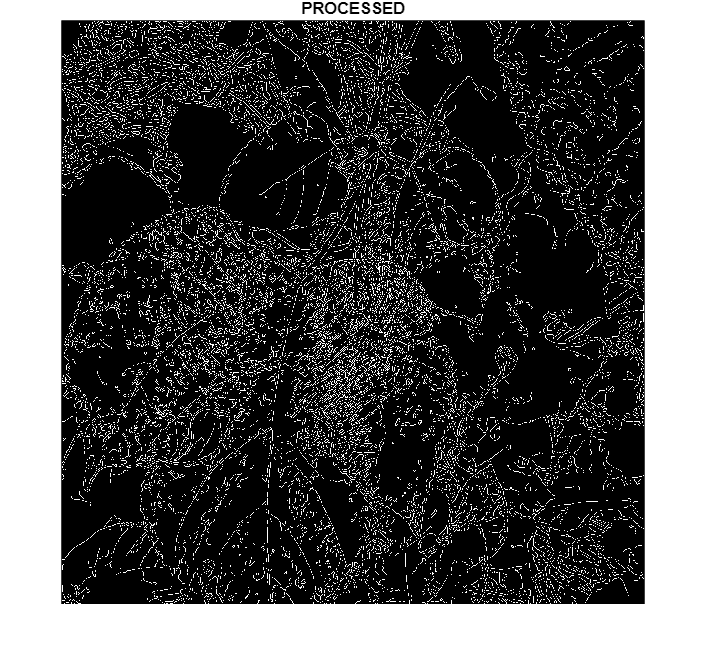

leafnames={'botleaf','speargrass','mangoleaf','pawpaw leaf','simpleleaf',};
leaftype={'simple','compound','compound','compound','compound','compound','compound'};
leafvenation={'network','parallel','network','network','network','network','network'};
shape={'oval','enlongated','lanceshaped','serrated','oval','heartshaped','oval'};
texture={'rough','rough','smooth','smooth','smooth','hairy','smooth'};
% CREATING AN EMPTY STRUCTURAL ARRAY TO HOLD ALL DATA
Leaves=struct();
for K=1:length(leafnames)
        Leaves(K).Name=leafnames{K};
        Leaves(K).LEAFTYPE= leaftype{K};
        Leaves(K).LeafVenation= leafvenation{K};
        Leaves(K).shape=shape{K};
        Leaves(K).texture=texture{K};
        % READING THE RAW LEAF IMAGE TAKEN BY THE CAMERA
        imgFileName=sprintf('leaf_%d.jpeg',K);
        Leaves(K).original=imread("C:\Users\AMI GENT\OneDrive\Desktop\leaf photos\leaf 1.jpeg");
        imshow(Leaves(K).original)
        I=Leaves(K).original;
        % CONVERTING THE RGB IMAGE TO GRAYSCALE
        Leaves(K).Grayimage=rgb2gray(I);
        % PERFORMING THE THRESHHOLDING AND SEGEMENTATION
        threshlevel=graythresh(Leaves(K).Grayimage);
        Leaves(K).Binaryimage=imbinarize(Leaves(K).Grayimage,threshlevel);
        Leaves(K).EdgeImg=edge(Leaves(K).Grayimage,"canny");
        EdgeImg=edge(Leaves(K).Grayimage,"canny");
        Leaves(K).Processedimage=EdgeImg
        imshow(Leaves(K).Processedimage);
        title('PROCESSED')
        % ("==========================FINISHED===========================")
end